# Chapter 2, Section 3 (Part 1)

The goal of this activity is to demonstrate what is known as the linear dependence and the linear independence of a set of vectors. Let's begin with a definition.

**Definition:** Let $S=\left\{\vec v_1,\vec v_2,\ldots,\vec v_m\right\}$ be a collection of vectors in $R^n$. This set of vectors is **linearly independent** if the vector equation


$$c_1\vec v_1+c_2\vec v_2+\cdots+c_m\vec v_m=\vec0$$


has only a **trivial **solution; that is, each of the constants are equal to zero $(c_1=0, c_2=0, \ldots, c_m=0)$. If the vector equation has a **nontrivial** solution, then the vectors are linearly dependent.

# Example #1

Determine if the set of vectors


$$\vec v_1=\pmatrix{1\cr -2\cr1},\qquad \vec v_1=\pmatrix{2\cr 1\cr 2},\qquad\text{and}\qquad\vec v_3=\pmatrix{-1\cr 2\cr 3}$$


are linearly independent or linearly dependent.

**Solution:** This set of vectors is linearly independent if and only if the vector equation


$$c_1\pmatrix{1\cr -2\cr 1}+c_2\pmatrix{2\cr 1\cr 2}+c_3\pmatrix{-1\cr 2\cr 3}=\pmatrix{0\cr 0\cr 0}$$


has only a trivial solution (i.e., each $c_i=0$). Let's write this in matrix form. 


$$\pmatrix{1 & 2 & -1\cr -2 & 1 & 2\cr 1 & 2 & 3}\pmatrix{c_1\cr c_2\cr c_3}=\pmatrix{0\cr 0 \cr 0}$$


Let's set up the augmented matrix for this system and put it in row echelon form. 


$$\pmatrix{1 & 2 & -1 & 0\cr -2 & 1 & 2 & 0\cr 1 & 2 & 3 & 0}\ \matrix{~\cr R_2+2R_1\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{[1] & 2 & -1 & 0\cr 0 & [5] & 0 & 0\cr 0 & 0 & [4] & 0}$$


Note that we have a pivot variable in each of the three columns representing $c_1$, $c_2$, and $c_3$, so this has a unique solution $(c_1,c_2,c_3)=(0,0,0)$. Of course, if this is not clear, we can add some steps.


$$\begin{array}{rcl}
c_1+2c_2-c_3&=&0\\
5c_2&=&0\\
4c_3&=&0
\end{array}$$


Using back substitution, $c_3=0$ and $c_2=0$. Substituting these in the first equation gives us:


$$\begin{array}{rcl}
c_1+2(0)-0&=&0\\
c_1&=&0
\end{array}$$


Therefore, the vector equation


$$c_1\pmatrix{1\cr -2\cr 1}+c_2\pmatrix{2\cr 1\cr 2}+c_3\pmatrix{-1\cr 2\cr 3}=\pmatrix{0\cr 0\cr 0}$$


has only the trivial solution $c_1=0$, $c_2=0$, and $c_3=0$, so the vectors are linearly independent. 

# Theorem

A set of nonzero vectors is linearly dependent if an only if at least one of the vectors is a linear combination of the other vectors in the set.

**Proof: **We have an "if and only if" statement again, so we need to prove two things:

- If $S=\left\{\vec v_1, \vec v_2, \cdots, \vec v_n\right\}$ is a set of linearly dependent vectors, then at least one of the vectors is a linear combination of the other vectors in the set.

- If at least one of the vectors is a linear combination of the other vectors in the set, then $S=\left\{\vec v_1, \vec v_2, \cdots, \vec v_n\right\}$ is a set of linearly dependent vectors.

**Part 1: ** Assume that $S=\left\{\vec v_1, \vec v_2, \cdots, \vec v_n\right\}$ is a set of linearly dependent vectors. This means that we have a nontrivial linear combination that equals the zero vector.


$$c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n=\vec 0$$


We know that not all values of $c_i$ are equal to zero, so let's assume $c_k\ne 0$, where $1\le k\le n$. Then we can manipulate our vector equation as follows.


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+\cdots+c_{k-1}\vec v_{k-1}+c_k\vec v_k+c_{k+1}\vec v_{k+1}+c_n\vec v_n&=&\vec 0\\
c_k\vec v_k&=&-c_1\vec v_1-c_2\vec v_2-\cdots-c_{k-1}\vec v_{k-1}-c_{k+1}\vec v_{k+1}-\cdots-c_n\vec v_n\\
\vec v_k&=&-\frac{c_1}{c_k}\vec v_1-\frac{c_2}{c_k}\vec v_2-\cdots-\frac{c_{k-1}}{c_k}\vec v_{k-1}-\frac{c_{k+1}}{c_k}\vec v_{k+1}-\cdots-\frac{c_n}{c_k}\vec v_n
\end{array}$$


Because $c_k\ne 0$, we could divide both sides by $c_k$. Note that we've shown that one of the vectors can be written as a linear combination of the other vectors, so we've proved part 1.

**Part 2: **Assume that one of the vectors in $S=\left\{\vec v_1, \vec v_2, \cdots, \vec v_n\right\}$ can be written as a linear combination of the other vectors in the set. We'll assume that $\vec v_k$ can be written as a linear combination of the other vectors, where $1\le k\le n$. 


$$\begin{array}{rcl}
\vec v_k&=&c_1\vec v_1+c_2\vec v_2+\cdots+c_{k-1}\vec v_{k-1}+c_{k+1}\vec v_{k+1}+\cdots +c_n\vec v_n\\
1\vec v_k&=&c_1\vec v_1+c_2\vec v_2+\cdots+c_{k-1}\vec v_{k-1}+c_{k+1}\vec v_{k+1}+\cdots +c_n\vec v_n\\
\end{array}$$


Now we will move the $1\vec v_k$ to the other side of the equation.


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+\cdots+c_{k-1}\vec v_{k-1}+(-1)\vec v_k+c_{k+1}\vec v_{k+1}+\cdots +c_n\vec v_n&=&\vec 0
\end{array}$$


Thus, we have a nontrivial linear combination (see the $-1$ is not zero) that equals the zero vector. Hence the vectors in the set $S=\left\{\vec v_1, \vec v_2, \cdots, \vec v_n\right\}$ are linearly dependent.

Because we have proved part 1 and part 2, we have proved the theorem.

# Visualizing Example #1

In Example #1, we showed that the vectors


$$\vec v_1=\pmatrix{1\cr -2\cr1},\qquad \vec v_1=\pmatrix{2\cr 1\cr 2},\qquad\text{and}\qquad\vec v_3=\pmatrix{-1\cr 2\cr 3}$$


are linearly independent. By the theorem we just proved, none of these vectors can be written as a linear combination of the other vectors. Let's sketch the plane spanned by the vectors $\vec v_1$ and $\vec v_2$.


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{1\cr -2\cr 1}+t\pmatrix{2\cr 1\cr 2}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{s+2t\cr -2s+t\cr s+2t}
\end{array}
$$
 

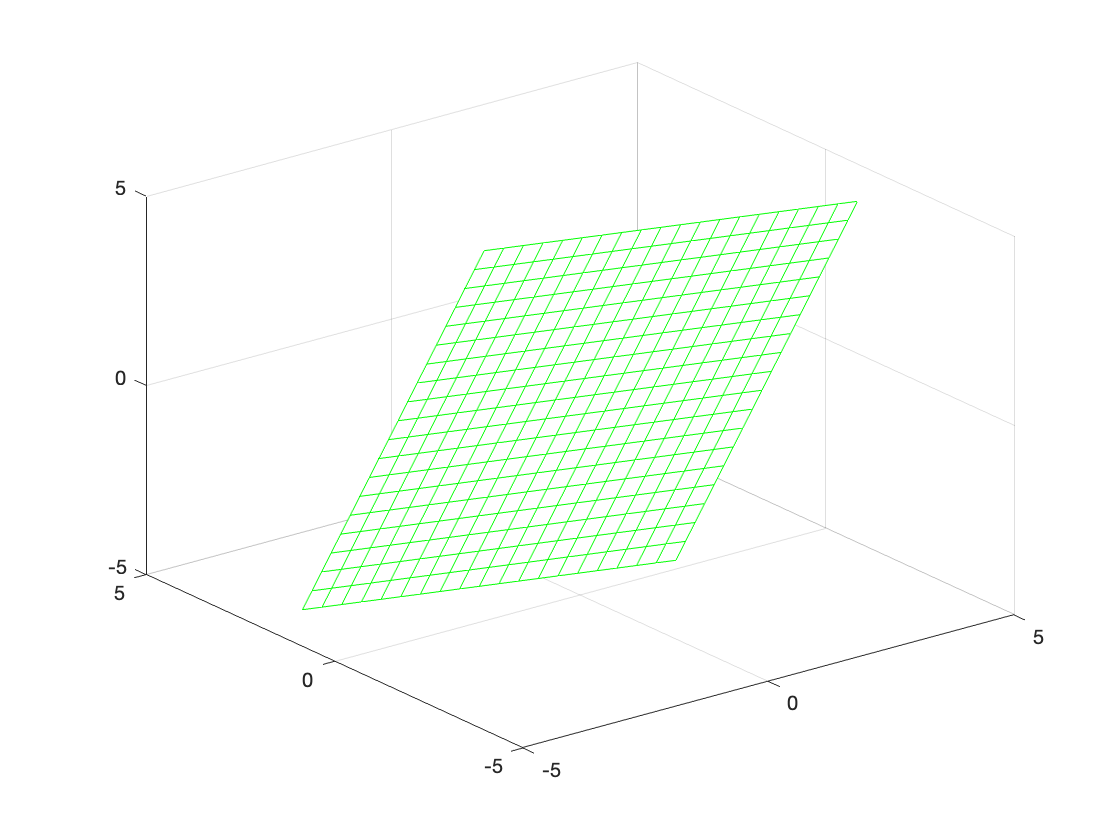

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=S+2*T; Y=-2*S+T; Z=S+2*T;
mesh(X,Y,Z,'EdgeColor','g')

Let's add our vectors to our image. We expect $\vec v_1$ and $\vec v_2$ to lie in the plane, but $\vec v_3$ will not lie in the plane.

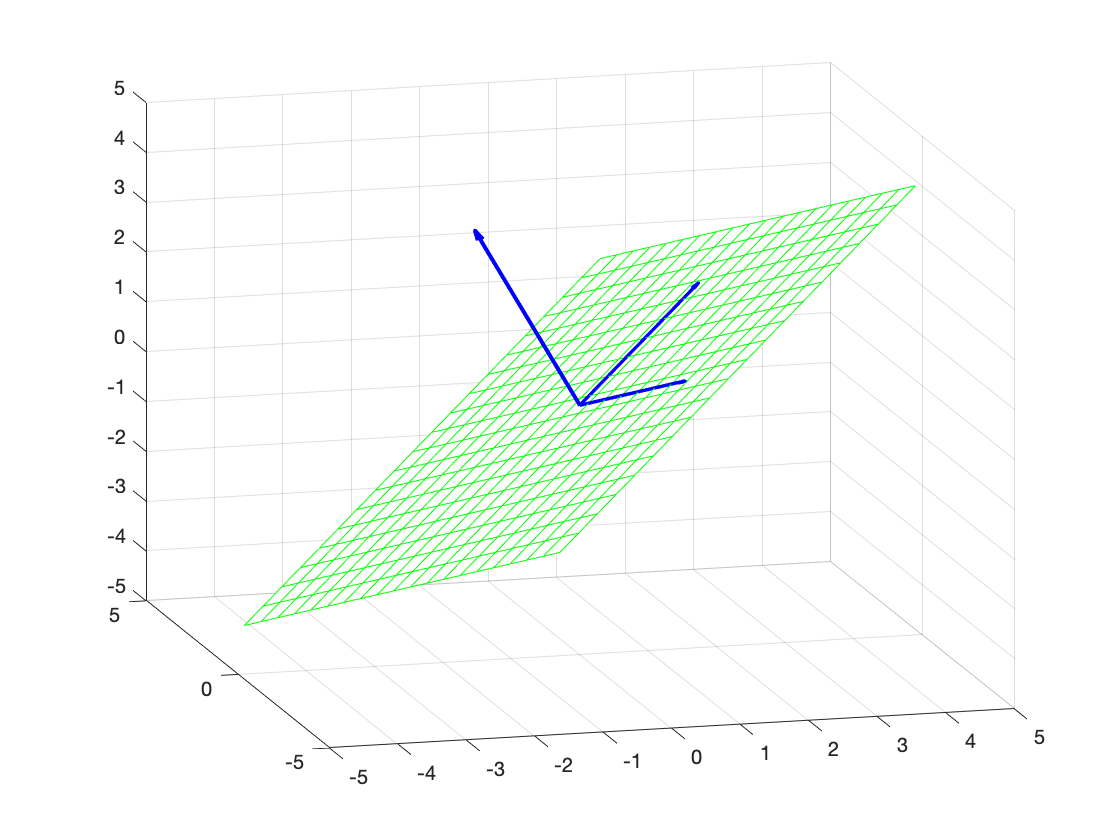

s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=S+2*T; Y=-2*S+T; Z=S+2*T;
mesh(X,Y,Z,'EdgeColor','g')
hold on
quiver3(0,0,0,1,-2,1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,2,1,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,-1,2,3,0,'LineWidth',2,'Color','b')
view(-15,17)
hold off

Indeed, the vectors $\vec v_1$ and $\vec v_2$ line in the plane, but the vector $\vec v_3$ does not lie in the plane. This means that $\vec v_3$ cannot be written as a linear combination of the vectors $\vec v_1$ and $\vec v_2$, because any linear combination of the vectors $\vec v_1$ and $\vec v_2$ will lie in the plane, but $\vec v_3$ does not lie in the plane. 

Similarly, we could sketch the plane spanned by the vectors $\vec v_1$ and $\vec v_3$ and see that the vector $\vec v_2$ does not lie in the plane spanned by the vectors $\vec v_1$ and $\vec v_3$. Similarly, we could sketch the plane spanned by the vectors $\vec v_2$ and $\vec v_3$ and see that the vector $\vec v_1$ does not lie in the plane spanned by the vectors $\vec v_2$ and $\vec v_3$.

It is visually clear that none of these three vectors can be written as a linear combination of the other two, so by our theorem above, these three vectors are linearly independent.

# Example #2

Determine if the set of vectors


$$\vec v_1=\pmatrix{1\cr 2\cr-1},\qquad \vec v_2=\pmatrix{-1\cr 2\cr 2},\qquad\text{and}\qquad\vec v_3=\pmatrix{1\cr 6\cr 0}$$


are linearly independent or linearly dependent.

**Solution:** This set of vectors is linearly independent if and only if the vector equation


$$c_1\pmatrix{1\cr 2\cr -1}+c_2\pmatrix{-1\cr 2\cr 2}+c_3\pmatrix{1\cr 6\cr 0}=\pmatrix{0\cr 0\cr 0}$$


has only a trivial solution (i.e., each $c_i=0$). Let's write this in matrix form. 


$$\pmatrix{1 & -1 & 1\cr 2 & 2 & 6\cr -1 & 2 & 0}\pmatrix{c_1\cr c_2\cr c_3}=\pmatrix{0\cr 0 \cr 0}$$


Let's set up the augmented matrix for this system and put it in row echelon form. 


$$\pmatrix{1 & -1 & 1 & 0\cr 2 & 2 & 6 & 0\cr -1 & 2 & 0 & 0}\ \matrix{~\cr R_2-2R_1\cr R_3+R_1}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 1 & 0\cr 0 & 4 & 4 & 0\cr 0 & 1 & 1 & 0}$$


Next,


$$\pmatrix{1 & -1 & 1 & 0\cr 0 & 4 & 4 & 0\cr 0 & 1 & 1 & 0}\ \matrix{~\cr ~\cr R_3-(1/4)R_2}\qquad\longrightarrow\qquad\pmatrix{[1] & -1 & 1 & 0\cr 0 & [4] & 4 & 0\cr 0 & 0 & 0 & 0}$$


Note that we have pivot variables in columns one and two representing $c_1$ and $c_2$, but a free variable in column three representing $c_3$. This system has an infinite number of soluitons for  $(c_1,c_2,c_3)$. 

Therefore, the vector equation


$$c_1\pmatrix{1\cr 2\cr -1}+c_2\pmatrix{-1\cr 2\cr 2}+c_3\pmatrix{1\cr 6\cr 0}=\pmatrix{0\cr 0\cr 0}$$


has an infinite number of nontrivial solutions, so the vectors are linearly dependent.

# Visualizing Example #2

In Example #2, we showed that the vectors


$$\vec v_1=\pmatrix{1\cr 2\cr-1},\qquad \vec v_1=\pmatrix{-1\cr 2\cr 2},\qquad\text{and}\qquad\vec v_3=\pmatrix{1\cr 6\cr 0}$$


are linearly independent. By the theorem we just proved, at  least one of these vectors can be written as a linear combination of the other vectors. Let's sketch the plane spanned by the vectors $\vec v_1$ and $\vec v_2$.


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&s\pmatrix{1\cr 2\cr -1}+t\pmatrix{-1\cr 2\cr 2}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{s-t\cr 2s+2t\cr -s+2t}
\end{array}
$$


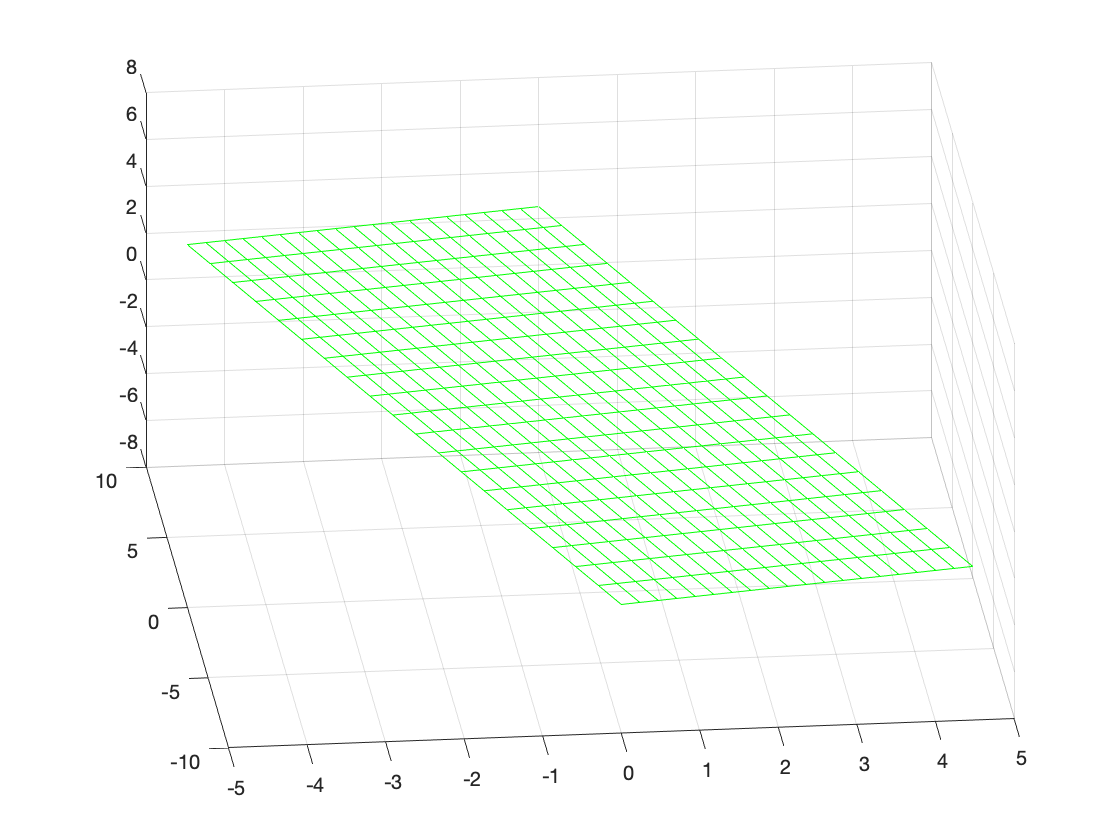

s=linspace(-2.5,2.5,20);
t=linspace(-2.5,2.5,20);
[S,T]=meshgrid(s,t);
X=S-T; Y=2*S+2*T; Z=-S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceColor','none')
view(-6,37)

Let's add our vectors to our image. We know that $\vec v_1$ and $\vec v_2$ lie in our plane, but because we know that the vectors are linearly dependent, our new theorem tells us that one vector can be written as a linear combination of the other vectors. This means that all three vectors must lie in the same plane.

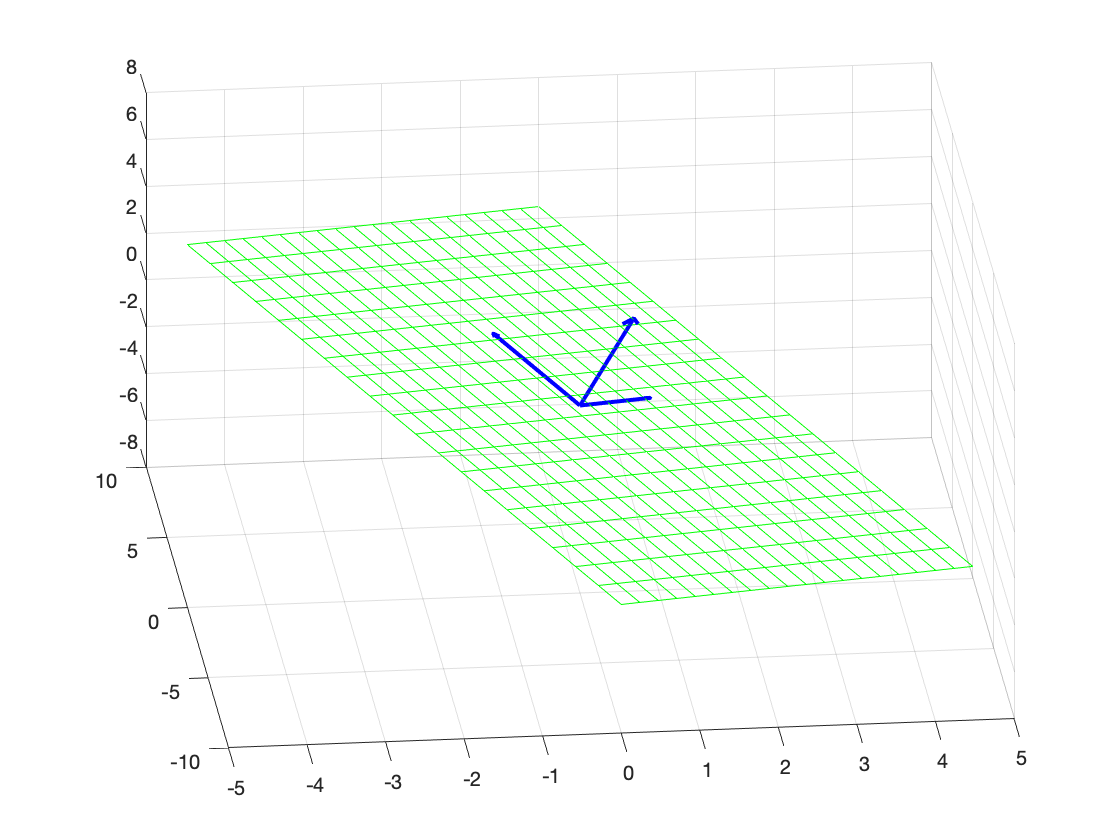

s=linspace(-2.5,2.5,20);
t=linspace(-2.5,2.5,20);
[S,T]=meshgrid(s,t);
X=S-T; Y=2*S+2*T; Z=-S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceColor','none')
hold on
quiver3(0,0,0,1,2,-1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,-1,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,1,6,0,0,'LineWidth',2,'Color','b')
hold off
view(-6,37)

We can rotate this image using Matlab to get a better visualization.

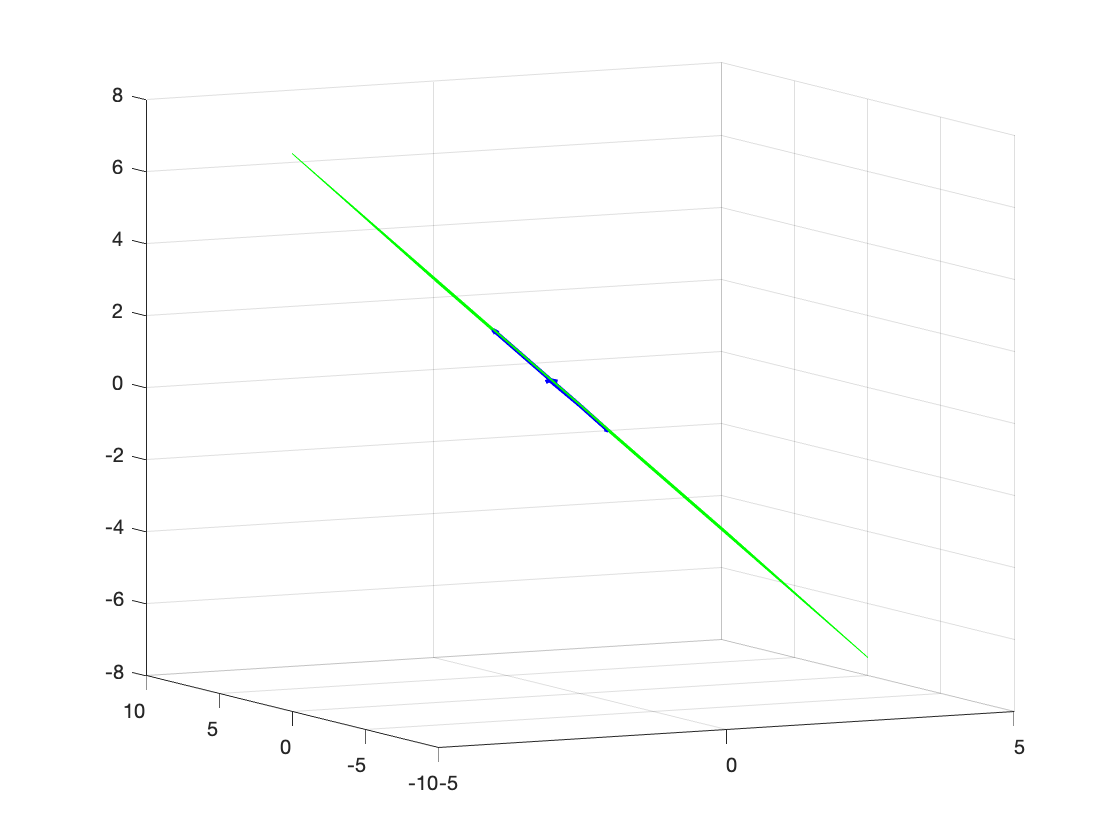

s=linspace(-2.5,2.5,20);
t=linspace(-2.5,2.5,20);
[S,T]=meshgrid(s,t);
X=S-T; Y=2*S+2*T; Z=-S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceColor','none')
hold on
quiver3(0,0,0,1,2,-1,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,-1,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,1,6,0,0,'LineWidth',2,'Color','b')
hold off
view(-27,8)

Wow! All three definitely lie in the plane, so they are linearly dependent.

# Two Vectors

It is very easy to determine whether two vectors are linearly dependent or independent. Suppose one vector $\vec v_1$ is a constant multiply of a second vector $\vec v_2$; that is, 


$$\vec v_1=c\vec v_2$$


Then we can move the vector $c\vec v_2$ over to the other side of the equation and write:


$$1\vec v_1-c\vec v_2=\vec 0$$


Thus, we have a nontrivial linear combination that equals the zero vector, so they are linearly dependent.

# Example #3

Are the two vectors


$$\vec v_1=\pmatrix{1\cr -2}\qquad\text{and}\qquad \vec v_2=\pmatrix{-2\cr 4}$$


linearly dependent or linearly independent?

**Solution:** Note that


$$-2\pmatrix{1\cr -2}=\pmatrix{-2\cr 4}$$


which is equivalent to:


$$2\pmatrix{1\cr -2}+1\pmatrix{-2\cr 4}=\pmatrix{0\cr 0}$$


Therefore, we've shown a nontrivial linear combination, so they are linearly dependent. Let's visualize what these two linearly dependent vectors look like. First, let's draw a line in the direction of $(1,-2)^T$. The line would be all vectors $(x,y)^T$ that are scalar multiples of $(1,-2)^T$.


$$\begin{array}{rcl}
\pmatrix{x\cr y}&=&t\pmatrix{1\cr -2}\\
\pmatrix{x\cr y}&=&\pmatrix{t\cr -2t}
\end{array}
$$


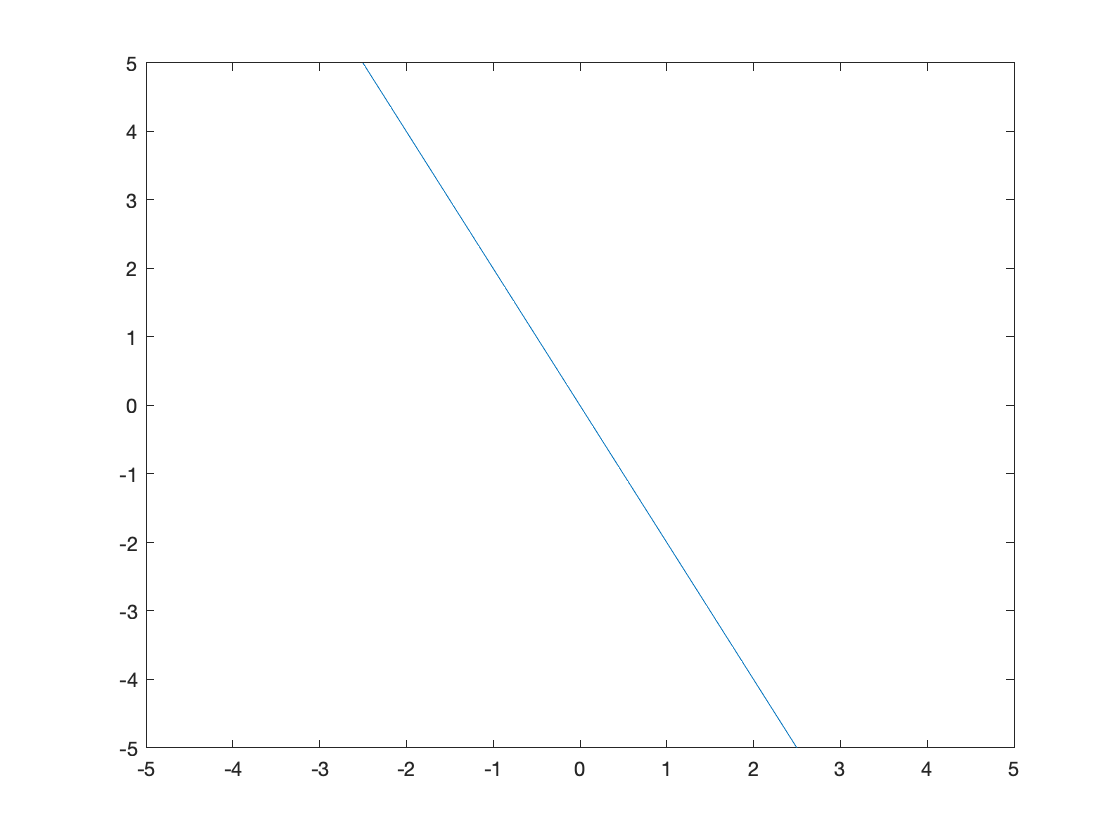

figure
t=linspace(-5,5);
x=t;
y=-2*t;
plot(x,y)
axis([-5,5,-5,5])

Now, let's add our vectors and prettify our image.

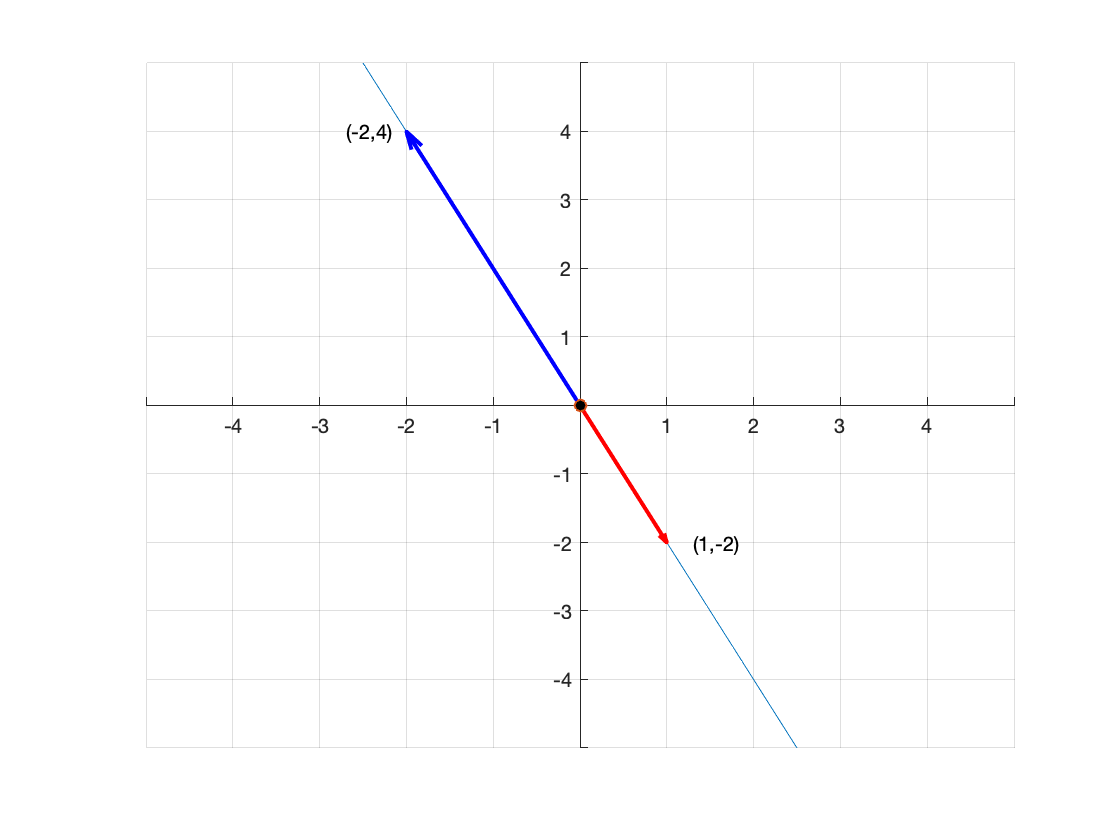

figure
hold on
t=linspace(-5,5);
x=t;
y=-2*t;
plot(x,y)
quiver(0,0,1,-2,0,'LineWidth',2,'Color','r')
quiver(0,0,-2,4,0,'LineWidth',2,'Color','b')
plot(0,0,'o','MarkerFaceColor','black')
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
grid on
text(-2.7,4,'(-2,4)')
text(1.3,-2,'(1,-2)')
hold off

Note that the two vectors are parallel, lying on the same line. They are linearly dependent.

# Example #4

Are the vectors 


$$\vec v_1=\pmatrix{2\cr -3}\qquad\text{and}\qquad\vec v_2=\pmatrix{3\cr 1}$$


linearly dependent or linearly independent?

**Solution: ** Note that $\vec v_1$ is **not** a constant multiple of $\vec v_2$, so they are linearly independent. Let's see what they look like.

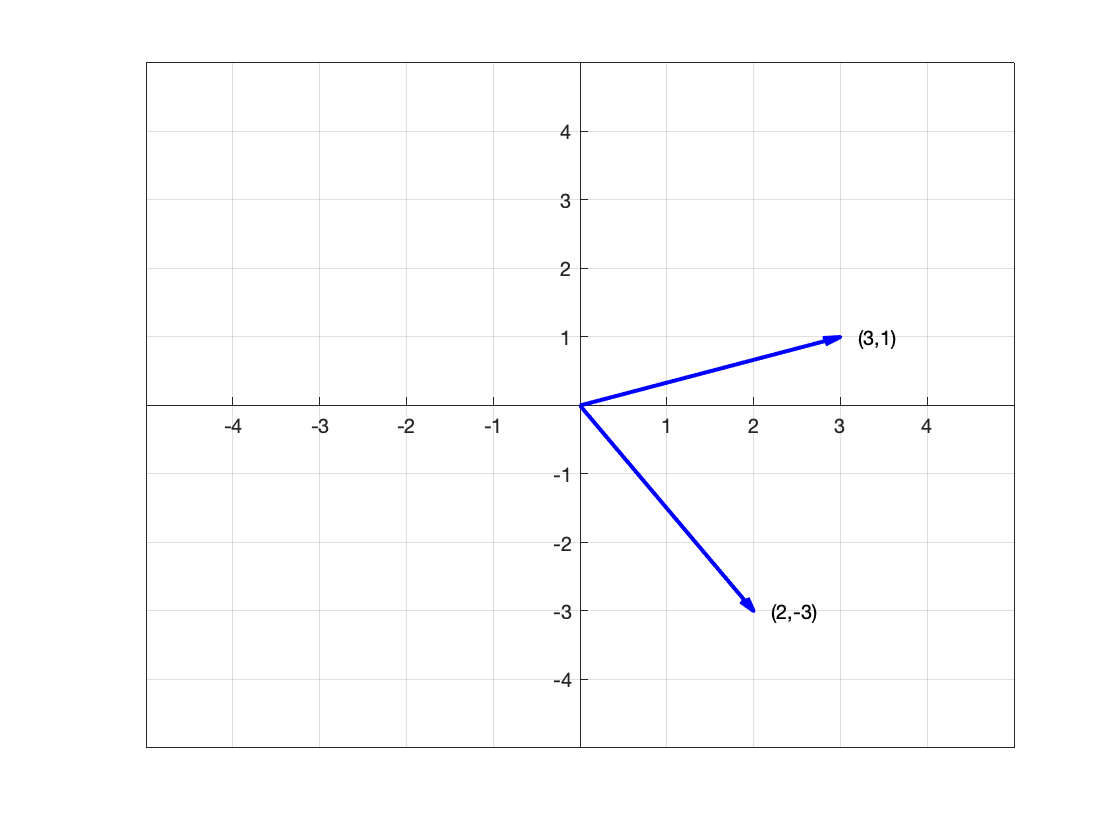

quiver(0,0,2,-3,0,'LineWidth',2,'Color','b')
hold on
quiver(0,0,3,1,0,'LineWidth',2,'Color','b')
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
grid on
text(2.2,-3,'(2,-3)')
text(3.2,1,'(3,1)')
hold off

Note that the two vectors $\vec v_1$ and $\vec v_2$ are not parallel. They are linearly independent.

# Example #5

Are the vectors


$$\vec v_1=\pmatrix{1\cr-2\cr1}\qquad\text{and}\qquad\vec v_2=\pmatrix{-2\cr 4\cr -2}$$


linearly dependent or linearly independent?

**Solution:** Noties that 


$$\pmatrix{-2\cr 4\cr -2}=-2\pmatrix{1\cr -2\cr 1}$$


or equivalently,


$$2\pmatrix{1\cr -2\cr 1}+\pmatrix{-2\cr 4\cr -2}=\pmatrix{0\cr 0\cr0}$$


so we have a nontrivial linear combination that equals the zero matrix. Thus, the vectors $\vec v_1$ and $\vec v_2$ are linearly dependent. What do they look like? Note that this time our line will be:


$$\begin{array}{rcl}
\pmatrix{x\cr y\cr z}&=&t\pmatrix{1\cr -2\cr 1}\\
\pmatrix{x\cr y\cr z}&=&\pmatrix{t\cr -2t\cr t}\\
\end{array}$$
 

Or we could use the second vector instead. 

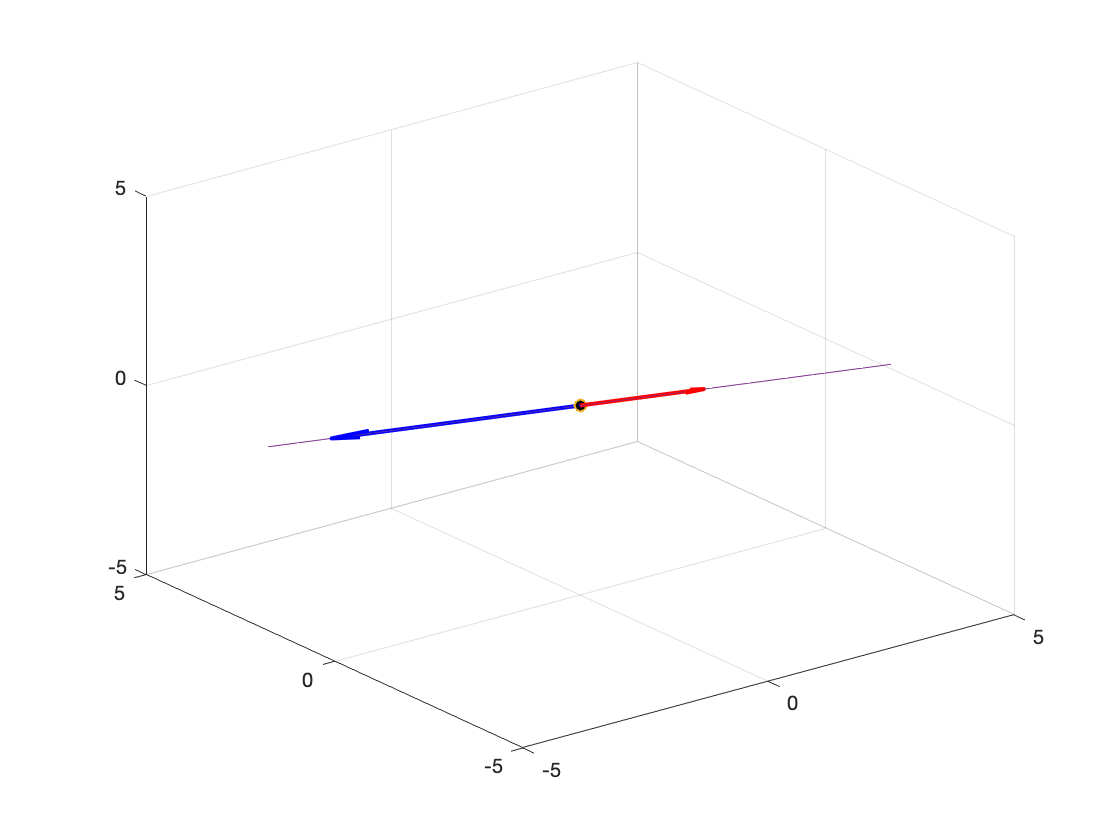

figure
hold on
quiver3(0,0,0,-2,4,-2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver3(0,0,0,1,-2,1,0,'LineWidth',2,'Color','r','MaxHeadSize',0.5)
plot3(0,0,0,'o','MarkerFaceColor','k')
t=linspace(-5,5);
x=t;y=-2*t;z=t;
plot3(x,y,z)
axis([-5,5,-5,5,-5,5])
grid on
view(3)
hold off

Note that the two vectors are parallel, lying on the same line. They are linearly dependent.

# Example #6

Are the vectors 


$$\vec v_1=\pmatrix{1\cr 2\cr 0},\qquad \vec v_2=\pmatrix{-1\cr 2 \cr 0},\qquad \vec v_3=\pmatrix{0\cr 0\cr 3},\qquad\text{and}\qquad\vec v_4\pmatrix{0\cr 4\cr 3}$$


linearly independent or linearly dependent?

**Solution: **Set up the equation


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+c_3\vec v_3+c_4\vec v_4&=&\vec 0\\
c_1\pmatrix{1\cr 2\cr 0}+c_2\pmatrix{-1\cr 2\cr 0}+c_3\pmatrix{0\cr 0\cr 3}+c_4\pmatrix{0\cr 4\cr 3}&=&\pmatrix{0\cr0\cr0}\\
\pmatrix{1 & -1 & 0 & 0\cr 2 & 2 & 0 & 4\cr 0 & 0 & 3 & 3}\pmatrix{c_1\cr c_2\cr c_3\cr c_4}&=&\pmatrix{0\cr 0 \cr 0}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\begin{array}{rcl}
\pmatrix{1 & -1 & 0 & 0 & 0\cr 2 & 2 & 0 & 4 & 0\cr 0 & 0 & 3 & 3 & 0}\ \matrix{~\cr R_2-2R_1\cr~}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 0 & 0 & 0\cr 0 & 4 & 0 & 4 & 0\cr 0 & 0 & 3 & 3& 0}
\end{array}$$


Next,


$$\begin{array}{rcl}
\pmatrix{1 & -1 & 0 & 0 & 0\cr 0 & 4 & 0 & 4 & 0\cr 0 & 0 & 3 & 3& 0}\ \matrix{~\cr (1/4)R_2\cr(1/3)R_3}\qquad\longrightarrow\qquad\pmatrix{1 & -1 & 0 & 0 & 0\cr 0 & 1 & 0 & 1 & 0\cr 0 & 0 & 1 & 1& 0}
\end{array}$$


Next,


$$\begin{array}{rcl}
\pmatrix{1 & -1 & 0 & 0 & 0\cr 0 & 1 & 0 & 1 & 0\cr 0 & 0 & 1 & 1& 0}\ \matrix{R_1+R_2\cr~\cr ~}\qquad\longrightarrow\qquad\pmatrix{[1] & 0 & 0 & 1 & 0\cr 0 & [1] & 0 & 1 & 0\cr 0 & 0 & [1] & 1& 0}
\end{array}$$


Note that we have three pivot variables for $c_1$, $c_2$, and $c_3$, but $c_4$ is a free variable. Therefore, there are an infinite number of solutions. Thus, the vectors $\vec v_1$, $\vec v_2$, $\vec v_3$, and $\vec v_4$ are linearly dependent.

Let's visualize this result.

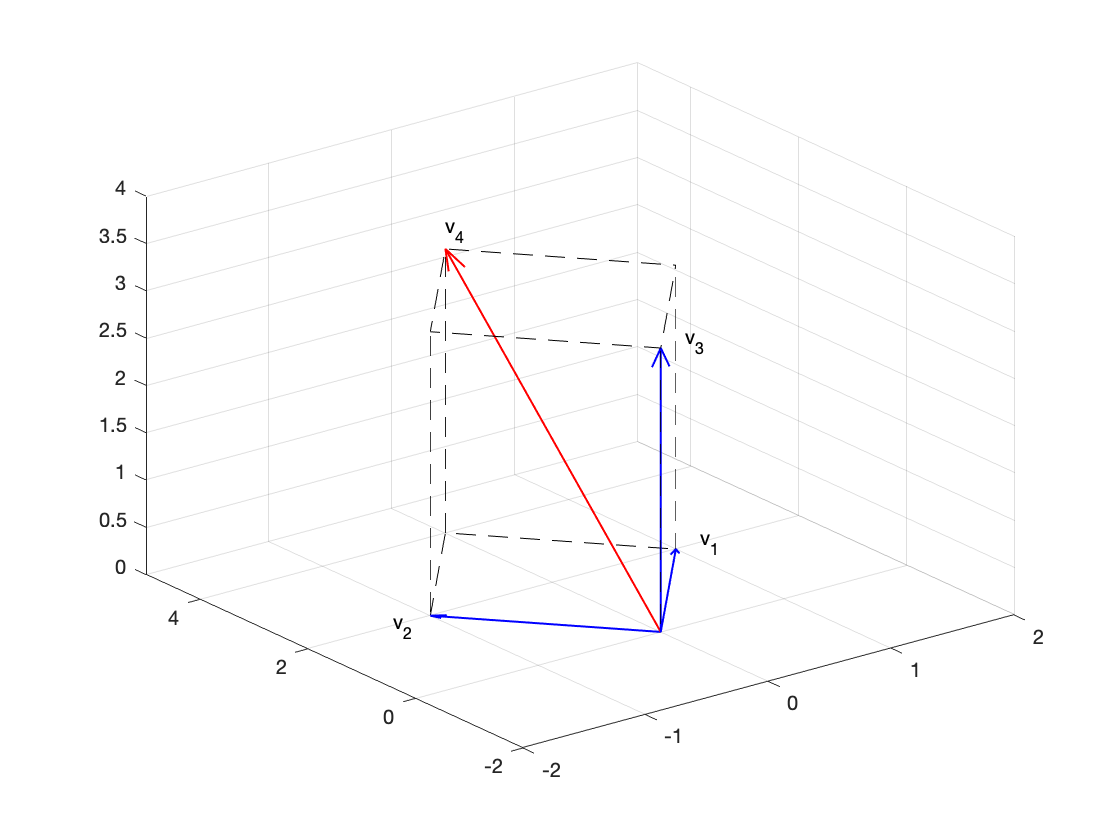

quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
hold on
quiver3(0,0,0,-1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,0,0,3,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,0,4,3,0,'LineWidth',1,'Color','r')
line([1,0,-1],[2,4,2],[0,0,0],'LineStyle','--','Color','k')
line([1,0,-1,0,1],[2,4,2,0,2],[3,3,3,3,3],'LineStyle','--','Color','k')
line([1,1],[2,2],[0,3],'LineStyle','--','Color','k')
line([0,0],[4,4],[0,3],'LineStyle','--','Color','k')
line([-1,-1],[2,2],[0,3],'LineStyle','--','Color','k')
line([0,0],[0,0],[0,3],'LineStyle','--','Color','k')
axis([-2,2,-2,5,0,4])
text(1.2,2,0,'v_1')
text(-1.3,2,0,'v_2')
text(0.2,0,3,'v_3')
text(0,4,3.2,'v_4')
hold off

Note that $\vec v_4$ is a linear combination (parallelepiped method) of $\vec v_1$, $\vec v_2$, and $\vec v_3$, showing convincing evidence that $\vec v_1$, $\vec v_2$, $\vec v_3$, and $\vec v_4$ are linearly dependent.

Did we waste a lot of time on Example #6? The answer is "Yes." If the number of vectors is larger than the number of entries in each vector, then the vectors will be linearly dependent.

# Theorem

Let $S=\left\{\vec v_1, \vec v_2, \ldots,\vec v_n\right\}$ be a set of vectors in $R^m$. If $n>m$, then the set $S$ is linearly dependent. 

**Proof:** Our vectors are in $R^m$, so each have $m$ rows. If we set up the linear combination


$$c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n=\vec 0$$


in matrix form, we get:


$$\pmatrix{\vec v_1 & \vec v_2 & \cdots & \vec v_n}\pmatrix{c_1\cr c_2\cr \vdots\cr c_n}=\pmatrix{0\cr 0\cr \vdots\cr 0}$$


This matrix equation is in the form $A\vec c=\vec 0$, where the matrix $A$ has $m$ rows and $n$ columns. If $n>m$, the the number of columns is greater than the number of rows, which means we will have at least one free variable when we row reduce, meaning we have an infinite number of solutions. Therefore, we've shown that the vectors are linearly dependent because our linear combination that equals zero has a non-trivial solution.